This tutorial is based on content from the cbm manual, and the paper describing cbm.

Hiararchical parameter estimation is one approach used for characterising population parameters for a computational model. HPE uses an expectation-maximisation algorithm to 1. estimate individual parameters given the group-level distribution, and 2. update group parameters given current individual parameters. These two steps are completed on alternate iterations of the expectation-maximisation algorithm. HPE assumes that for a given model, all parameters are normally distributed.  HPE also assumes that a given model is responsible for generating data in all subjects because the model identity is included as a fixed effect. This means that during each participant has equal influence on group parameters, means and variances during parameter estimation, even if their data are better explained by alternative models. Furthermore, model comparison involves the evidence for each model across all subjects, which also treats a model as a fixed effect. Here, the authors extend the HPE approach by including an additional level to the hierarchy that specifies which model generated the data for each subject. model inference is then achieved through joint inferences over models and their parameters.

Mean-field variational Bayes is used for hierarchical bayesian inference as an extension of expectation-maximisation, because it is capable of handling multiple latent variables. There are four steps involved in each iteration of the hierarchical bayesian inference algorithm. 1. Calculate summary statistics, 2. update estimates of the posterior distribution for group parameters, 3. update esimates of the posterior for individual parameters, 4. update estimates of responsibility for each model in generating given data. 

First, we will prepare the behavioural data so that it is in a format that CBM likes. CBM likes data formatted as a cell array. Each cell within the array is a different participant. Within each participant structure there are three arrays. These arrays are called 'action', 'outcomes', and side. The action array contains the participant's choice for each trial. The 'outcomes' array includes the response to each choice. The 'side' array includes the key press for each choice. Please note, it is important to understand that trials where participants do not respond are removed at this stage, in line with current modelling approaches. Therefore, there may be differences in the size of action and outcome vectors between participants. The following code for data preparation is also available as a separate matlab script in this directory called 'prep_data.m'.

%reset the matlab environment before starting
clear 
clc
warning('off')
%initialise variable for output
file = 'C:\Users\Brendan\University of Reading\neuroade - Projects\project_SRonline\data\sona-pilot\sronline_sona-pilot_reversal-learning_preprocessed.csv'; 
all_data = readtable(file);
idx = unique(all_data.id);
data = {};
for id = 1:size(idx) %participants included in CBM analysis

    ppt = idx(id);
    %load behavioural data
    %please ammend this path if you are not running this script on my machine
    df = all_data(all_data.id == ppt,:);
    df = rmmissing(df);
    %there is a quirk in the formatting of the text file that means the
    %following IDs need to be indexed differently. This does not impact the
    %output data
    %extract actions
    out.actions = table2array(df(:,4));
    %extract outcomes
    out.outcome = table2array(df(:,7));
    %remove trials where no response was recorded
    %extract keypress
    %out.side = string(table2array(df(:,14)));
    %remove trials where no response was recorded
    %out.side(out.side(:,1) =='NaN')=[];
    %check if right key pressed
    %out.right = out.side;
    %out.right(out.right(:,1) == "r") = 1;
    %out.right(out.right(:,1) == "b") = 0;
    %out.right = str2double(out.right);
    %append data to cell array
    data{end+1} = out;
end
%reshape cell array to a column vector
data = reshape(data, max(size(data)), 1);
%save output
save('all_data.mat', 'data')

In this task, participants completed a probabilistic reversal learning (PRL) task. In the PRL task participants were presented with two options, each was associated with a different probability of giving reward. One option resulted in reward 80% of the time, the other 20% of the time. Participants were tasked with maximising reward in the task. The reward probabilities of choices would change approximately every 15, such that the more rewarding option would become less rewarding (80% reward changes to 20%) and vice versa for the less rewarding option (20% reward changes to 80%). At this points, participants need to switch their preferential responding from one option to the other to continue maximising reward gain. 

First, we will load the behavioural data and check our models are compatiable with CBM. For the purpose of this tutorial we will use the following model files 'model_RL.m' and 'model_Kanen_4c.m' These models can be defined as:

[include model definition and formulae here]

clear 
%load the data
fdata = load("all_data.mat");
data = fdata.data;

%get data for one subject, create random parameters, and check the models
%run
subj1 = data{14};
parameters = randn(1,2)

parameters =    -0.8566   -0.3887


loglik = model_RL(parameters, subj1)

loglik = -80.1108

parameters = randn(1,3)

parameters =     1.0285   -0.2397   -0.4516


%loglik = model_dualRL(parameters, subj1)
parameters = randn(1,3)

parameters =    -0.9793   -1.1334    0.0221


%loglik = model_Li_hybrid(parameters, subj1)

If we get log likelihood values returned for each of the models, then we know that our models are compatiable with CBM. These values should be real negative numbers. After checking the models run correctly, we can now use CBM to fit the models to our data. Firstly, the CBM function cbm_lap is used to fit a model to each participant separately. This model fit is non-hierarchical, and requires a normally distributed prior for each parameter; it uses Laplace approximation of the joint distribution of data and parameters to calculate maximum-a-posteriori estimates of parameters. A maximum-a-posteriori estimate is the mode of a posterior distribution; it is similar to the maximum likelihood esimation. Maximum likelihood esimation could be considered to be a case of maximum-a-posteriori esimation, with the prior being a uniform distribution. For the following section we will set the prior mean = 0 and variance = 6.25, in line with Daw et al (2019) [https://doi.org/10.1371/journal.pcbi.1007043](https://doi.org/10.1371/journal.pcbi.1007043).

%define the inputs needed for the function cbm_lap. These are:
% [CBM, SUCCESS] = cbm_lap(DATA, MODEL, PRIOR, FNAME, PCONFIG)
% DATA:  data (Nx1 cell) where N is number of samples
% MODEL: a function-handle to the model computing log-likelihood of DATA 
% given some paramete 
% PRIOR: a struct with two fields: mean and variance, as the gaussian prior
%   PRIOR.mu is a d-by-1 vector, where d is the number of parameters
%   (dimension)
%   PRIOR.variance is scaler or a vector or matrix indicating prior
%   variance. If it is scaler, prior variance is diagonal with 
%   PRIOR.variance as diagonal elements. If it is a vector, prior variance
%   is diag(PRIOR.variance).
% FNAME: filename for saving the output (leave it empty for not saving)
% PCONFIG: a struct for configuration (optional); see cbm_lap.m for more info
v = 6.25;
prior_RL = struct('mean',zeros(2,1),'variance',v);
prior_dualRL = struct('mean',zeros(3,1),'variance',v);
%prior_Li_hybrid = struct('mean',zeros(3,1),'variance',v);
fname_RL = 'lap_RL.mat';
fname_dualRL = 'lap_dualRL.mat';
%fname_Li_hybrid = 'lap_Li_hybrid.mat';

%now cbm_lap will be run for each of the models
cbm_lap(data, @model_RL, prior_RL, fname_RL);

cbm_lap                                           07-Jun-2021 13:43:36
Number of samples: 20
Number of parameters: 2

Number of initializations: 14
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
done :]


cbm_lap(data, @model_dualRL, prior_dualRL, fname_dualRL);

cbm_lap                                           07-Jun-2021 13:43:37
Number of samples: 20
Number of parameters: 3

Number of initializations: 21
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
done :]


%cbm_lap(data, @model_Li_hybrid, prior_Li_hybrid, fname_Li_hybrid);

Now we can inspect the maximum-a-posteriori estimates from cbm_lap. These parameters are normally distributed, and their order is dependent on how the variables are coded in the model. The first column will be the first parameter and so on. Each row will represent the maximum-a-posterior estimate for each a given participant. 

fname = load('lap_RL.mat');
cbm = fname.cbm;
cbm.output.parameters

ans =     1.7145    0.0499
    0.7837   -0.5638
   -2.5371    1.7877
    2.4257    0.6156
    2.1038    0.1467
   -0.0408   -0.5155
    2.2976   -0.0594
    3.0423   -0.5810
    2.0943   -1.0139
    2.1488    0.5159


fname = load('lap_dualRL.mat');
cbm = fname.cbm;
cbm.output.parameters

ans =     1.1746    1.8239    0.0917
    0.7743    0.4538   -0.5306
   -2.4682   -2.5457    1.7674
    1.4592    2.3929    0.6747
    1.9226    1.8217    0.1648
   -0.0768    0.0019   -0.5135
    1.3260    2.2406   -0.0064
    1.8593    2.8597   -0.5506
    0.1272    2.3689   -0.7830
   -1.1957    3.3050    1.6247


%fname = load('lap_Li_hybrid.mat');
%cbm = fname.cbm;
%cbm.output.parameters

Now  we can use the function cbm_hbi to do hierarchical bayesian inference. This function requires four inputs, these are:

cbm = cbm_hbi(data,models,fcbm_maps,fname,config,optimconfigs)

1st input: data for all subjects

2nd input: a cell input containing function handle to models

3rd input: another cell input containing file-address to files saved by cbm_lap

4th input: a file address for saving the output (optional)

5th input: is a struct, which configures hbi algorithm (optional); see cbm_hbi_config    

6th input: is another struct, which configures optimization algorithm (optional); see cbm_optim_config

%2nd input
models = {@model_RL, @model_dualRL};%, @model_Li_hybrid};
%3rd input
fcbm_maps = {'lap_RL.mat','lap_dualRL.mat'};%, 'lap_Li_hybrid.mat'};
fname = 'RL_drl.mat';
cbm_hbi(data,models,fcbm_maps,fname);

cbm_hbi_hbi                                       07-Jun-2021 13:43:39
Running hierarchical bayesian inference (HBI)...

HBI has been initialized according to
	lap_RL.mat [for model 1]
	lap_dualRL.mat [for model 2]
 
Number of samples: 20
Number of models: 2
Iteration 01
Iteration 02
	model frequencies (percent)
	model 1: 57.2| model 2: 42.8| 
                                                           dL:    4.58
                                                           dm:   42.81
                                                           dx:    0.31
Iteration 03
	model frequencies (percent)
	model 1: 63.5| model 2: 36.5| 
                                                           dL:    0.89
                                                           dm:    6.32
                                                           dx:    0.10
Iteration 04
	model frequencies (percent)
	model 1: 68.9| model 2: 31.1| 
         

For each iteration of the model fitting cbm_hbi will report a percentage of the participants who are best explained by each of the models. It will also report the change in log-likelihood of all data from the previous iteration, given the model space (dL); the percentage change in model frequencies from the previous iteration (dm); and the changes in parameters from the previous iteration (dx). By default, cbm_hbi stops when dx <0.01.

Now we will inspect the output from cbm_hbi

fname_hbi = load('RL_drl.mat');%load('RL_drl_li.mat');
cbm = fname_hbi.cbm;
cbm.output

ans = struct with fields:
                     parameters: {2×1 cell}
                 responsibility: [20×2 double]
                     group_mean: {[1.9950 0.0978]  [1.0712e-04 1.1252e-04 3.0554e-04]}
    group_hierarchical_errorbar: {[0.2587 0.1562]  [0.1402 0.1401 0.1405]}
                model_frequency: [0.9991 9.0195e-04]
                exceedance_prob: [1.0000 5.0951e-07]
      protected_exceedance_prob: [NaN NaN]


cbm.output.parameters will give you the parameters for each subject for each model

cbm.output.responsibility will describe the estimated responsibility that each model generated each individual's data. These sum to 1 for each subject. 

cbm.output.group_mean will give you the group mean for each parameter. These parameters are normally distributed because hierarchical bayesian inference assumes that parameters are normally distributed.

cbm.output.group_hierarchical_errorbar will give you the error for each group level parameter (standard mean error)

cbm.output.model_frequency will give you an estimate of how much each model is expressed across the group. This is useful for model comparison.

cbm.output.exceedance_prob will give you the probability that each model is the most likely model across the group

cbm.output.protected_exceedance_prob will give you the probability that each model is the most likely model across the group while accounting for the null hypothesis that no model is most likely.

Now we will plot the group parameters for the models.

plotting the group parameters of the most frequenct modelThere is no protected exceedance probability as cbm_hbi_null has not been executed
Plotting exceedance probability instead...


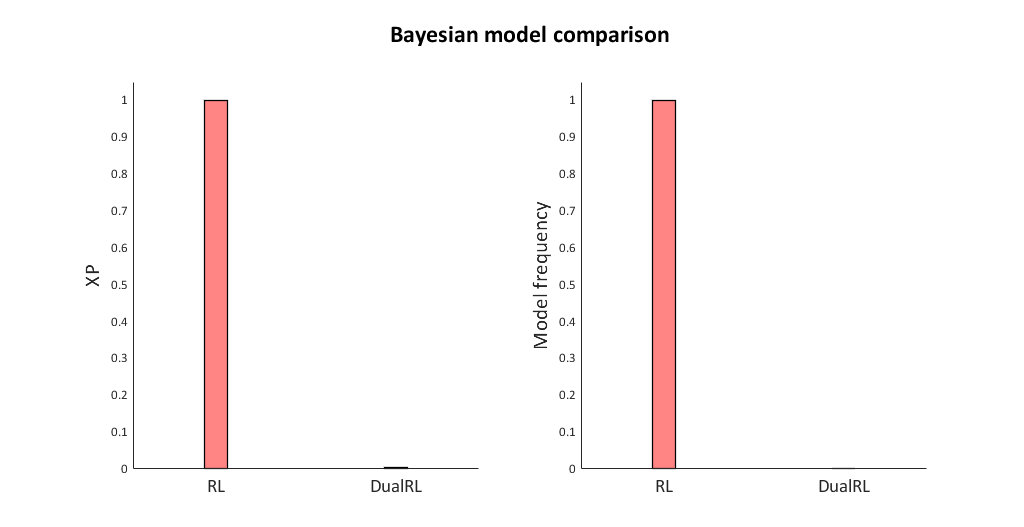

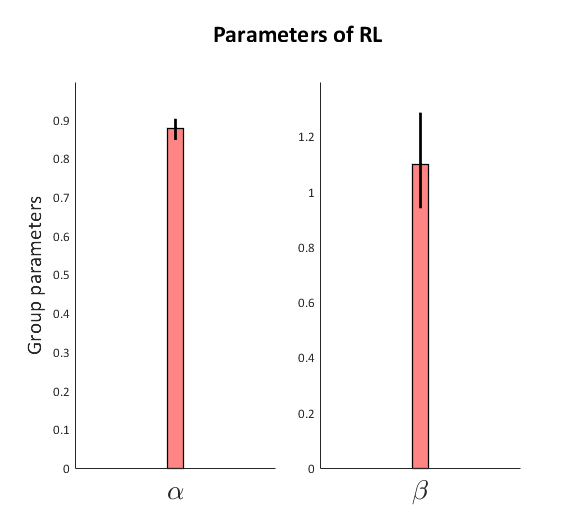

model_names = {'RL','DualRL'};%, 'Li hybrid'};
%param_names = {'\alpha^0','\eta','\kappa'};
param_names = {'\alpha','\beta'};
%transform = {'exp','sigmoid','sigmoid'};
transform = {'sigmoid','exp'};
cbm_hbi_plot('RL_drl.mat', model_names, param_names, transform);

%cbm_hbi_plot('RL_drl_li.mat', model_names, param_names, transform);

Now we will re-run HBI under the null hypothesis that no model is most likely across the population

cbm_hbi_null(data,'RL_drl.mat')

cbm_hbi_hbi                                       07-Jun-2021 13:43:43
Running hierarchical bayesian inference (HBI)- null mode...

HBI has been initialized according to
	lap_RL.mat [for model 1]
	lap_dualRL.mat [for model 2]
 
Number of samples: 20
Number of models: 2
Iteration 01
Iteration 02
                                                           dL:    4.32
                                                           dx:    0.32
Iteration 03
                                                           dL:    0.47
                                                           dx:    0.11
Iteration 04
                                                           dL:    0.07
                                                           dx:    0.06
Iteration 05
                                                           dL:   -0.00
                                                           dx:    0.04
Iteration 06
             

ans = struct with fields:
        method: 'hbi'
         input: [1×1 struct]
       profile: [1×1 struct]
          math: [1×1 struct]
        output: [1×1 struct]
    exceedance: [1×1 struct]


fname_hbi = load('RL_drl.mat');
cbm = fname_hbi.cbm;
xp = cbm.output.exceedance_prob

xp =     1.0000    0.0000


pxp = cbm.output.protected_exceedance_prob

pxp =     1.0000    0.0000


For each iteration cbm will report the change in log-likelihood of all data from the previous iteration, given the model space (dL); and the changes in parameters from the previous iteration (dx). You will also be able to seed the exceedance probability (xp) and the protected exceedance probability (pxp). We can now re-plot the model comparison parameters as we have pxp values.

plotting the group parameters of the most frequenct model

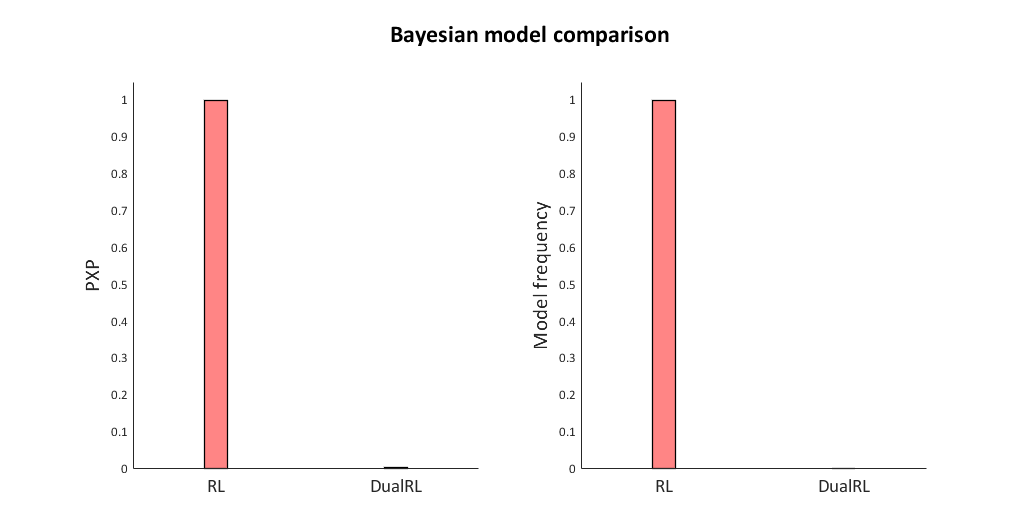

model_names = {'RL','DualRL'};%, 'Li hybrid'};
param_names = {'\alpha','\beta'};
transform = {'sigmoid','exp'};
cbm_hbi_plot('RL_drl.mat', model_names, param_names, transform);